Preliminary data visualization

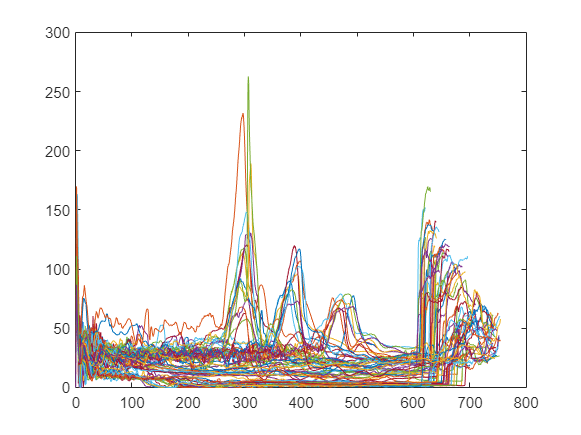

for i=1:81
    plot(disp(:,i),force(:,i));
    hold on;
end
hold off;

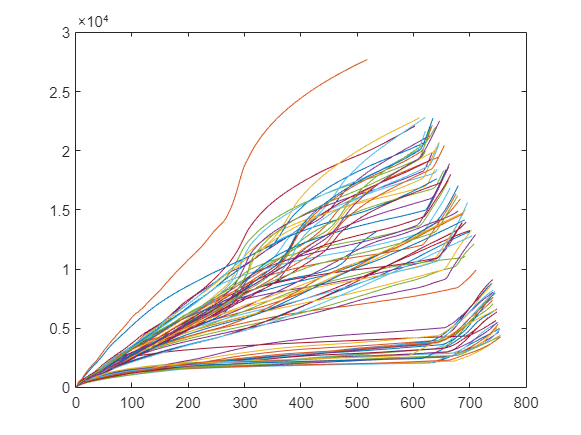


for i=1:81
    plot(disp(:,i),energy(:,i));
    hold on;
end
hold off;

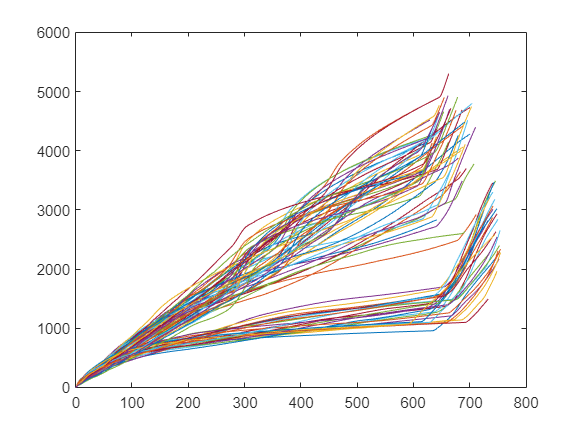


for i=1:81
    plot(disp(:,i),sea(:,i));
    hold on;
end
hold off;

Determine index at 260 mm crushed displacement.

index = zeros(1,81)

index =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i = 1:81
    x = disp(:,i)
    index(1,i)= find(x>259.5 & x<260.5,1) %% find an index of 260 mm disp +- 0.5 mm 
end

Unrecognized function or variable 'disp'.

Determine IPF within index range and SEA at specified index.

forcetarget = zeros(81,1)

forcetarget =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


seatarget = zeros(81,1)

seatarget =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for i =1:81
    forcetarget(i,1) = max(force(1:index(i),i)); %% IPF
    seatarget(i,1) = sea(index(i),i);   %% SEA
end

Just make whole data to be more readable via table.

targettable = table(forcetarget,seatarget,'VariableNames',["IPF [kN]" "SEA [J]"]);
%inputtable = table(input(:,1),input(:,2),input(:,3),input(:,4),'VariableNames',["TR [A2/A1]" "A2 [mm]" "L [mm]" "T [mm]"]);
%datatable = [inputtable targettable]

ready for model fitting!!

data = table2array(datatable)

data = 	1.0e+03 *

    0.0010    0.1200    0.3000    0.0020    0.1180    0.7961
    0.0010    0.1200    0.3000    0.0035    0.1180    1.4769
    0.0010    0.1200    0.3000    0.0050    0.1180    1.7975
    0.0010    0.1200    0.4000    0.0020    0.1204    0.8060
    0.0010    0.1200    0.4000    0.0035    0.1204    1.4875
    0.0010    0.1200    0.4000    0.0050    0.1205    1.8221
    0.0010    0.1200    0.5000    0.0020    0.1221    0.8606
    0.0010    0.1200    0.5000    0.0035    0.1221    1.4049
    0.0010    0.1200    0.5000    0.0050    0.1221    1.9555
    0.0010    0.1400    0.3000    0.0020    0.1398    0.8128
